Для построения графика функции одной переменной в декартовых координатах служит команда plot(X,Y) – строит график функции Y(X), где Y и X – вектора одинаковой длины. 

Разметкой осей и линиями сетки можно управлять с помощью команд: 

axis off – убирает с осей их обозначения и маркеры 

axis on – восстанавливает введенные ранее обозначения axis([xmin xmax ymin ymax]) – устанавливает диапазон координат по осям 

axis auto – устанавливает параметры осей по умолчанию 

axis equal - устанавливает параметры осей с одинаковым расстоянием между метками 

axis manual – «замораживает» масштаб осей в текущем состоянии 

grid on – добавляет сетку к текущему графику

grid off – отключает сетку. 

Для текстовых сообщений на графике служат команды: 

title(‘string’) – титульная надпись 

xlabel(‘string’) или ylabel(‘string’) – названия осей 

text(X,Y,’string’) – текст, начало которого находится в точке (X,Y) 

gtext(‘string’) – позиционирование текста с помощью мышки

legend(string1,string2,...,pos) – легенда, размещенная в зависимости от параметра pos (0 – лучшее место, 1 – верхний правый угол, 2 – верхний левый угол, 3 – нижний левый угол, 4 – нижний правый угол, -1 – справа от графика).

Для построения графиков в полярной системе координат служит команда polar(theta,ro) или polar(theta,ro,S) с синтаксисом, аналогичным plot

Для построения диаграмм служат команды: 

bar(Y) – столбцовый график элементов вектора Y (или bar(X,Y), где положение столбцов задается вектором X, или bar(X,Y,width,S) с заданной шириной столбцов, параметр S аналогичен рассмотренному ранее параметру для команды plot);

hist(...) – гистограмма, параметры те же, что у команды bar; 

stairs(...) – лестничный график, параметры те же, что у команды bar; 

rose(theta,N) – угловая гистограмма, N – число интервалов от 0 до 2*pi (по умолчанию 20).

Для построения трехмерных графиков служат команды:

meshgrid(X,Y) –задание опорной области для построения трехмерной поверхности; 

plot3(X,Y,Z) – трехмерный аналог команды plot, где X, Y, Z – матрицы одинакового размера, команда строит трехмерные точки и соединяет их отрезками прямых. 

Более наглядное изображение обеспечивают команды: 

mesh(X,Y,Z,C) – сетчатое изображение поверхности (C – цвет узловых точек, по умолчанию C=Z, т.е. цвет линий зависит от их высоты); 

meshc(...) - изображение поверхности и ее проекции в виде линий равного уровня; 

meshz(...) – построение поверхности столбцами; surf(X,Y,Z,C) – цветная параметрическая поверхность, цвет задается массивом С; 

surfc(...) – построение поверхности и ее проекции; 

surfl(...) – построение поверхности с подсветкой от источника света

Окраску поверхности и различные эффекты можно задать с помощью функций: 

colormap(S) – задает окраску тонами указанного цвета, например colormap(‘gray’); 

shading interp – устраняет изображение сетки и задает интерполяцию для оттенков цвета; 

colorbar – выдает на экран шкалу оттенков с соответствующими координатами; 

diffuse – задает эффект диффузионного рассеяния; 

lighting – управляет подсветкой; 

material – имитирует свойства рассеивания света различными материалами; 

specular – задает эффект зеркального отражения; 

view – задает положение точки просмотра;

rotate3d – задает поворот трехмерной фигуры.

**Задача.** Построить график поверхности $z=x^2 +y^2$ при 0 < x < 1, 0 < y < 1. И построить диаграмму(12x3) со случайными значениями с шириной столбцов 0.7

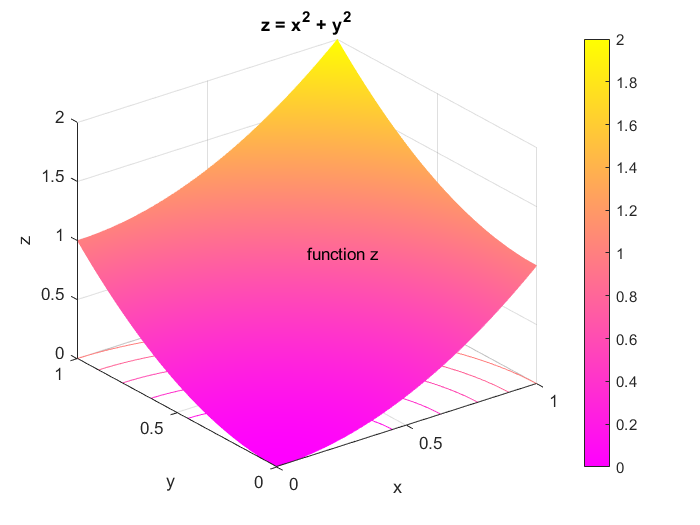

clear;
clc;
close all;

x1 = linspace(0, 1);
x2 = linspace(0, 1);

[X1, X2] = meshgrid(x1, x2);

Z = X1.^2 + X2.^2;

surfc(X1, X2, Z)
title('z = x^2 + y^2');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;
text(0.5, 0.5, 1,'function z'); 
shading interp;
colorbar;
colormap spring;
axis auto;

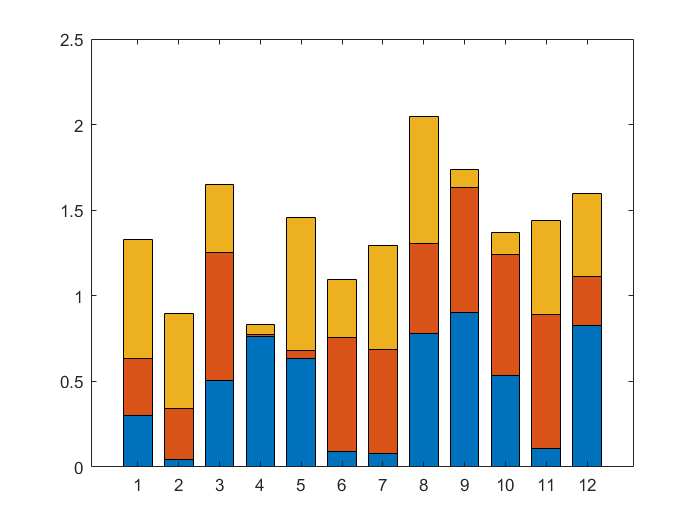



bar(rand(12,3), 0.7,'stacked')